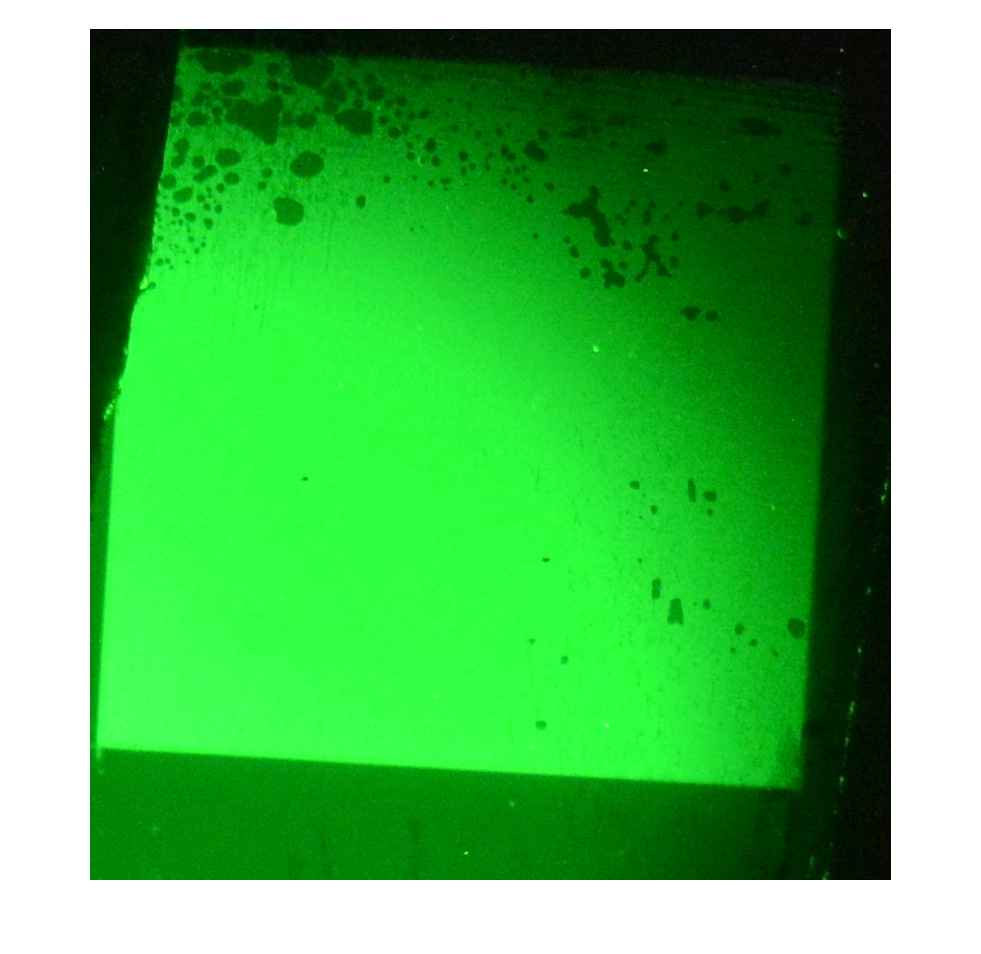

clear;
%Start with uploading and selecting the image
img = "BA_Silicon_membrane.jpg";  
%Select region of interest (ROI) from image for the ESF calculations.

I=imread(img);
%imshow(I);
x =2490;
y = 1070;
w = 800;
h = 850;
rect = [x y w h];
I_cropped = imcrop(I,rect) ;
imshow(I_cropped);

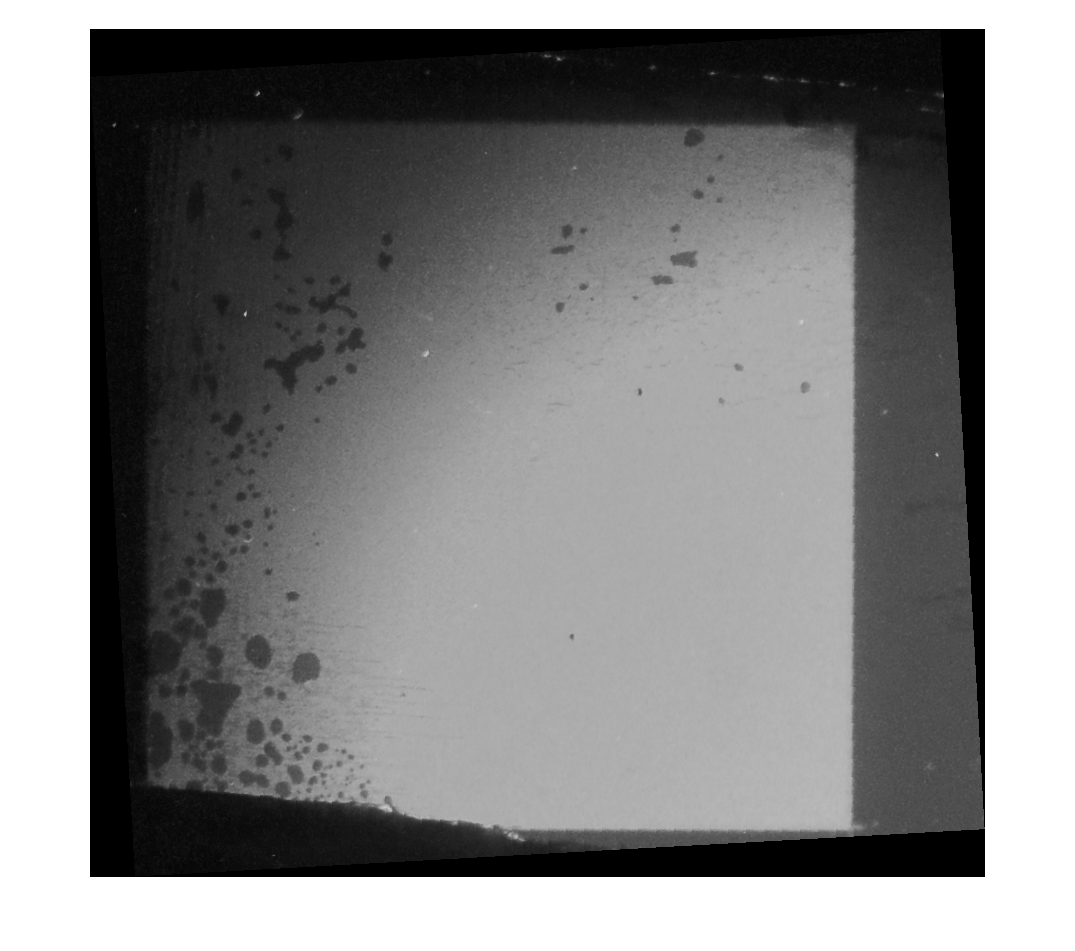


%Now convert the ROI to gray and rotate it, untill slanted edge and image
%edge are paralell. Afterwards show area again, to control the result.

I_cropped=imrotate(I_cropped,93.19);
GI_cropped = rgb2gray(I_cropped); 
imshow(GI_cropped);

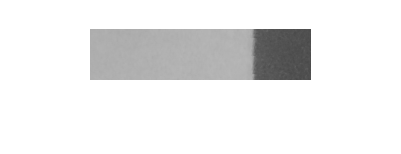

ROI =  GI_cropped(650:700, 600:820);            %Select the final ROI.
imshow(ROI);

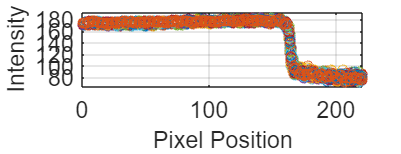

% ESF: Average Intensity over all rows, plot it. 

l = 1:size(ROI,2);
ll = length(l);
maxroi = max(ROI, [], 'all')+10;
minroi = min(ROI, [], 'all')-10;

%This plot shows the individual intensity of each pixel for each row.
plot(l,ROI','o')
% title('Edge Spread Function ')
xlabel('Pixel Position')
ylabel('Intensity')
grid on
fontsize(14,"points")
axis([0 ll minroi maxroi])

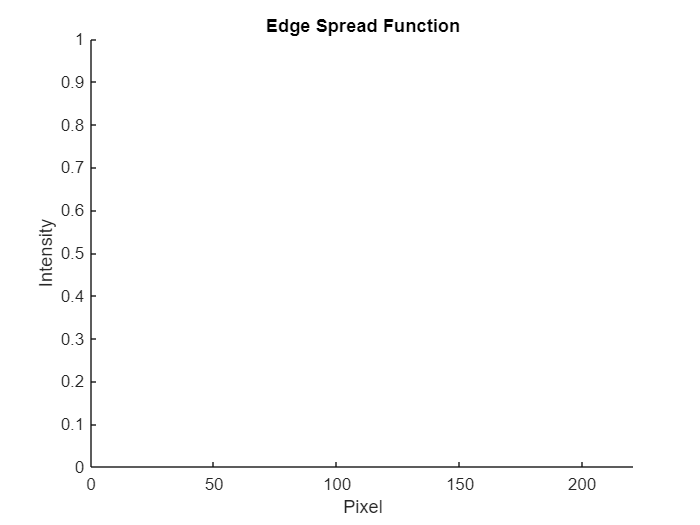


% Now calculate the averaged ESF, which will then be Fermi-Dirac fitted. 
figure;
ESF = mean(ROI);
selESF = ESF;         
%We can select a interval with the edge at its centre. Unnecessary pixel informations can be deselected.
% selESF = selESF(150:220);
l_selESf= 1:length(selESF);
selESF = selESF/max(selESF);

%This plot shows the averaged ESF values, normalized to 1. 
figure;
% plot(l_selESf,selESF, '-o','MarkerIndices',1:10:length(selESF));
title('Edge Spread Function')
xlabel('Pixel')
ylabel('Intensity')
axis([0 ll 0 1])


% Fermi Fit : Fit parameters of the Fermi-Dirac-function to the image data.
% x0 is an array with four parameters, x(1)-x(4). We give an initial guess
% for the fir parameters, then lsqnonlin searches for a local minimum.
fdfit = @(x)x(1)./(exp((l_selESf-x(2))./x(3))+1)+x(4)-selESF;
x0 = [0.8332,120,5,0.1424]

x0 =     0.8332  120.0000    5.0000    0.1424


x = lsqnonlin(fdfit,x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x =     0.5204  164.4720    1.2091    0.4610


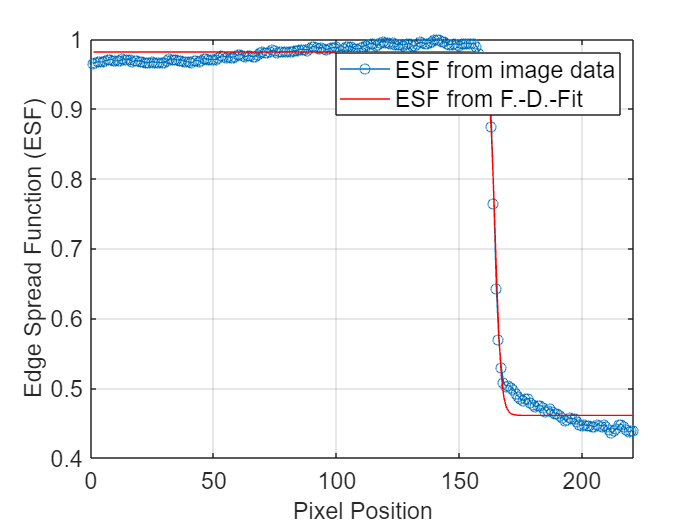

% Obtain the fitting parameters, which were calculated by lsqnonlin, for the DQE calculations later.
fdfit_para = x;
imgxsize = length(l_selESf);

% This plots the averaged ESF data and the matlab fitted Fermi-Dirac
% function in one plot, to illustrate the accuracy of the fit. Usually one
% can see deviations from the original data, especially around the turning
% points. The fit can be improved manually, if one uses the Curve Fitter
% App in Matlab.

figure;
plot(l_selESf,selESF,'-o',l_selESf,fdfit(x)+selESF,'-r');
% title('Fermi-Dirac-Fit of Data Points')
ylabel('Edge Spread Function (ESF)')
xlabel('Pixel Position')
legend('ESF from image data','ESF from F.-D.-Fit')
grid on
fontsize(14,"points")
axis([0 imgxsize 0.4 1])

%This only olots the F-D fit.
figure;
% plot(l_selESf,fdfit(x)+selESF,'-r');
title('Data Points with Fermi Fit')
ylabel('Intensity')
xlabel('Pixel')
axis([0 200 0 1])

%Option for manual fitting of F-D fit.
fdfit2 = @(b)b(1)./(exp((l_selESf-b(2))./b(3))+1)+b(4);
b = [91.2787,16.1,1.815,26.7067];
% plot(l_selESf,fdfit(x)+selESF,'-r',l_selESf,fdfit2(b),'-g',l_selESf,selESF,'-o')


%LSF: Deriviate averaged ESF and F-D fit. They are then plotted against
%one another.

selLSF= abs(diff(selESF));          % LSF from the ESF data
fun2 = fdfit(x)+selESF;     
fdfitLSF =abs(diff(fun2));        %LSF of the fitted Fermi-Dirac-ESF
e = 0:length(selLSF)-1;


% plot(e,fdfitLSF,'-r');
% title('LSF')
xlabel('pixel')
ylabel('Line Spread Function (LSF)')
legend('F.-D.-Fit')

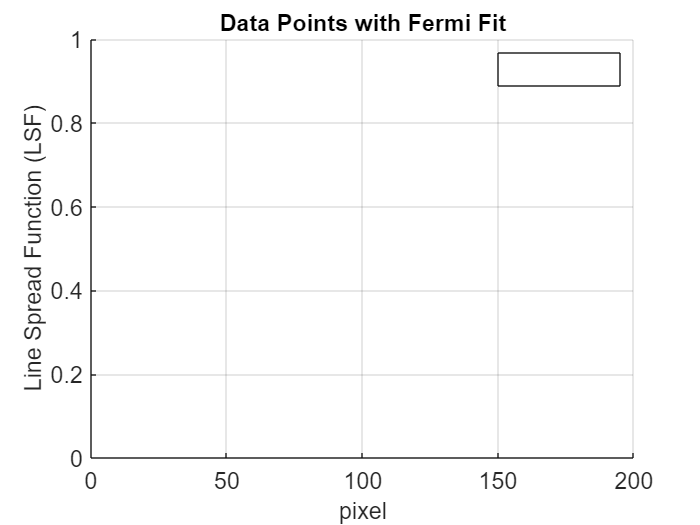

grid on
fontsize(14,"points")



figure;                    
% plot(e,selLSF,e,fdfitLSF,'-r');
% title('LSF')
xlabel('Pixel Position')
ylabel('LSF')
legend('ESF data','F.-D.-Fit')

fontsize(14,"points")
grid on

%Because the F-D fit is not always perfectly accurate, as mentionend
%before, one can also fit a Gaussian function of first or second order to the LSF data obtained from
%the original averaged ESF data.
% Gaussian Fit for LSF Data: The  fitting parameters are obtained using the
% Curve Fitting App.

a1 = 0.0965;
b1 = 11.0270;
c1 = 3.9814;

% First order:
gfLSF = a1.*exp(-((e-b1)./c1).^2);
% plot(e,gfLSF);
%Second order:
a22 =0.0803;
b22 =94.3473;
c22 =3.8359;
a2 =0.0063;
b2 = 96.0294;
c2 =97.1158;
gfLSF2 = a22.*exp(-((e-b22)./c22).^2) + a2.*exp(-(((e-b2)./c2).^2));
% plot(e,gfLSF2);

% Now Lets also compare all three plots with one another. For now i have deleted the
% Gaussian Fit first order: e,gfLSF,'< --g'.

% plot(e,selLSF,' -b',e,fdfitLSF,' -r', e,gfLSF2,' -g');
% title('Comparison of LSF')
xlabel('Pixel Position')
ylabel('Line Spread Function (LSF)')
legend('ESF data','F.-D.-Fit','Gaussian fit')

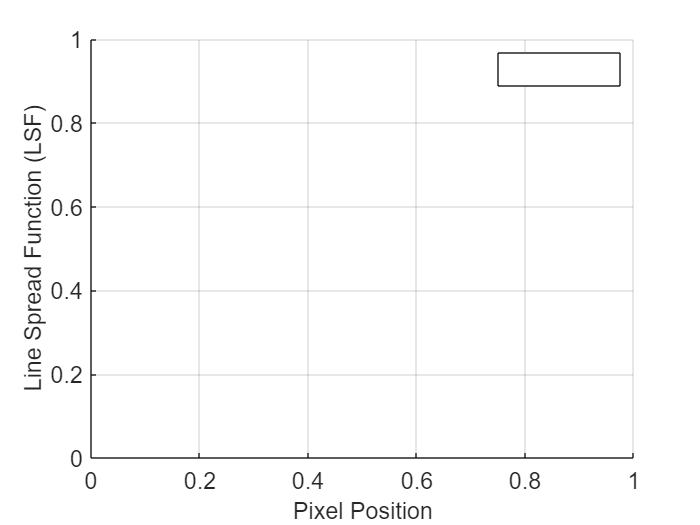

fontsize(14,"points")
grid on


%Aplication of a Hanning Window 

% % Length of the LSF
% N = length(e);
% 
% % Generate a 1D Hanning window of the same length as the LSF
% window = hann(N);
% 
% % Apply the Hanning window to the LSF
% windowed_lsf = lsf .* window;
% 
% % Plot the original and windowed LSF
% figure;
% subplot(2, 1, 1);
% plot(lsf);
% title('Original LSF');
% 
% subplot(2, 1, 2);
% plot(windowed_lsf);
% title('Windowed LSF');

%    MODULATION TRANSFER FUNCTION (MTF)

%Calculate the MTF by calcualting the Discrete Fourier Transform of the
%LSF. We compared the results for the different LSFs.

%First for the real LSF data
L = length(selLSF);        
n = 2^nextpow2(L);

selMTF =abs(fft(selLSF,n));        
selMTF = selMTF/max(selMTF);
sel_selMTF = selMTF(1:(length(selMTF)/2));         %Only interested in real parts of the LSF  
wl_selMTF = 0:length(selMTF)-1;
hl_selMTF = 0:length(sel_selMTF)-1;


%Now plot the data we receive for a first check. Due to the Fourier
%transform the result will include a real part and an imaginary part. This
%can be seen in the symmetry of the result. For later calculations, we are
%only interested in the real results.

% plot(wl_selMTF,selMTF,'^ -b');                      %Plotting ESF data
title('Whole MTF : Modulation Transfer Function from real ESF data')
ylabel('MTF')
xlabel('Cycles/set')
legend('MTf:real data')

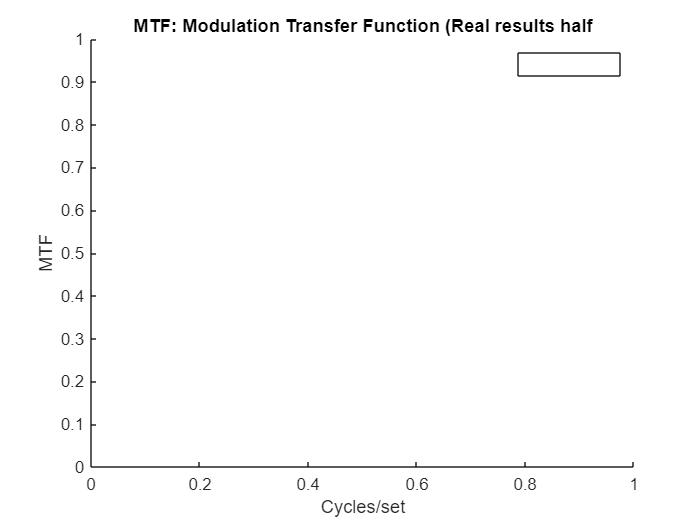


% Now plot only one half as we only need real results

% plot(hl_selMTF,sel_selMTF,'-o r','MarkerIndices',1:5:length(sel_selMTF));
title('MTF: Modulation Transfer Function (Real results half')
ylabel('MTF')
xlabel('Cycles/set')

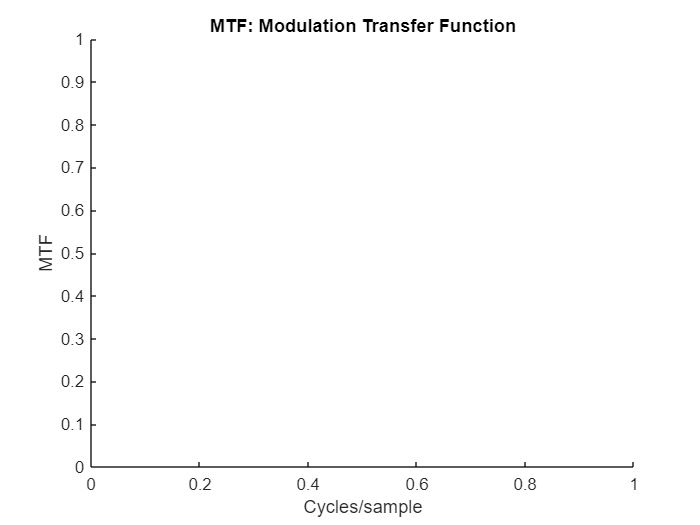


%We will now convert the frequency axis into different units. Matlab only
%knows the steps in naturel numbers. However, these are not the frequency
%results of the DFT.

%CYCLES PER SAMPLE

%Conversion to Cycles/sample, should show a fequency axis going from zero
%to one.Cycles are the amount of times, the DFT "cycles" through the set,
%which is a result of the DFT. Samples means the number of datapoints,
%which where used by the DFT.

set = 1/(length(hl_selMTF));

figure;
% plot(hl_selMTF*set,sel_selMTF,'-o r','MarkerIndices',1:5:length(sel_selMTF));
title('MTF: Modulation Transfer Function')
ylabel('MTF')
xlabel('Cycles/sample')


%LINEPAIRS PER MM

%Assuming we have one pixel per sample this is also the result in
%Cycles/pixel
%now as the last step, calculate the result in Lp/mm. We assume One cycle =
%one lp, and also one pixel = pixelpitch[mm]

pp = double(9.6.*(10.^-3)) %pixelpitch in mm

pp = 0.0096

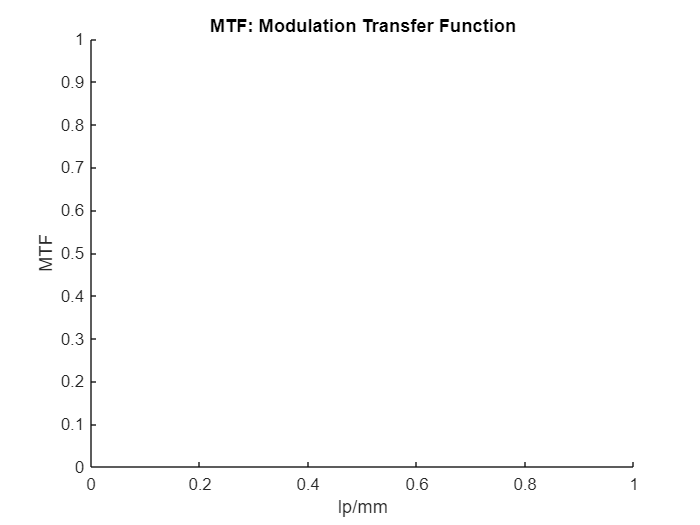

set = set*(1/pp);

figure;
% plot(hl_selMTF*set,sel_selMTF,'-o r','MarkerIndices',1:5:length(sel_selMTF));
title('MTF: Modulation Transfer Function')
ylabel('MTF')
xlabel('lp/mm')


%COMPARISON WITH FERMI FIT

%Now, as next test, we calcualte the MTF for the F.-D.-Fit, to compare the
%results.

figure;

L2 = length(fdfitLSF);         %Now the fitted Fermi-Dirac-LSF data
n = 2^nextpow2(L2);

fdfit_MTF =abs(fft(fdfitLSF,n));         %FT of the LSF
fdfit_MTF = fdfit_MTF/max(fdfit_MTF);    %Norm
hl_fdfitMTF = fdfit_MTF(1:length(fdfit_MTF)/2);  %Again only interested in the real results 
h = 0: length(hl_fdfitMTF)-1;


% plot(h,hl_fdfitMTF);
% title('MTF of F.-D.-Fit')
xlabel('Cycles/set')
ylabel('MTF')
legend('F.-D.-Fit ')

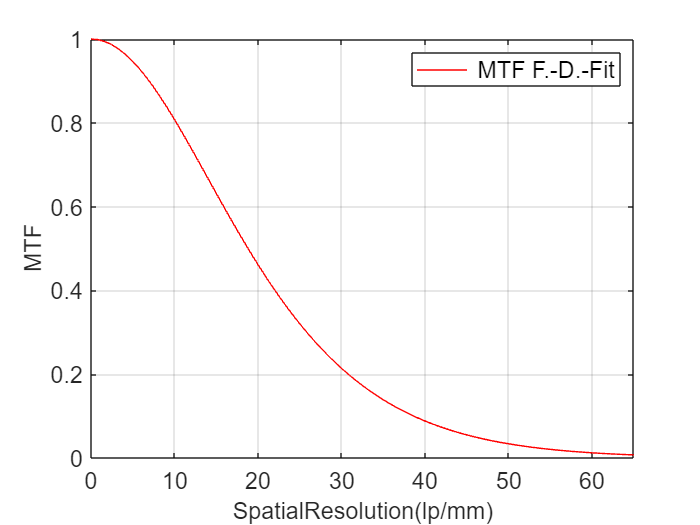

grid on
fontsize(14,"points")
axis([0 30 0 1])

%Conversion to lp/mm
fdfitset = 1/(length(hl_fdfitMTF));
psize = 9.6*10^(-3); % size of pixels in mm
fdfitset = fdfitset*(1/psize);
plot(h*fdfitset,hl_fdfitMTF,'-r');
% title('MTF: Modulation Transfer Function of F.-D.-Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('MTF')
legend(' MTF F.-D.-Fit ')
grid on
fontsize(14,"points")
axis([0 65 0 1])

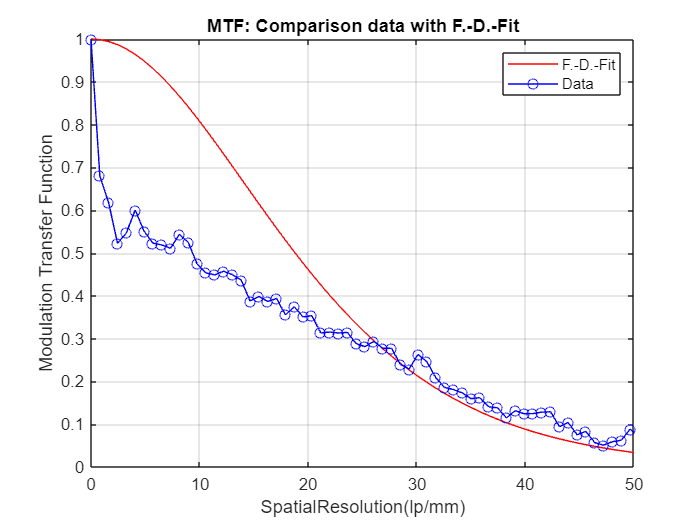


%Comparison of the MTF calculations using F-D fit and the averaged ESF
%data.

 plot(h*fdfitset,hl_fdfitMTF,'-r',h*fdfitset,sel_selMTF,'-o b');
title('MTF: Comparison data with F.-D.-Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('F.-D.-Fit','Data')
grid on
axis([0 50 0 1]);


% Now we do the same for the Gaussian Fit of the LSF.

figure;

L2 = length(gfLSF);         %Now the fitted Fermi-Dirac-LSF data
n = 2^nextpow2(L2);

gffit_MTF =abs(fft(gfLSF,n));         %
gffit_MTF = gffit_MTF/max(gffit_MTF);    %Norm
hl_gffitMTF = gffit_MTF(1:length(gffit_MTF)/2);
h_gffitMTF =0:length(hl_gffitMTF)-1;

psize =double(9.6.*(10.^-3));                    % size of pixels in mm
sf = 1./(length(hl_gffitMTF)*psize);     %Sampling Frequency


L3 = length(gfLSF2);
n = 2^nextpow2(L3);

gffit2_MTF =abs(fft(gfLSF2,n));         %
gffit2_MTF = gffit2_MTF/max(gffit2_MTF);    %Norm
hl_gffit2MTF = gffit2_MTF(1:length(gffit2_MTF)/2);
h_gffit2MTF =0:length(hl_gffit2MTF)-1;

psize = double(9.6.*(10.^-3));                    % size of pixels in mm
sf1 = 1./(length(hl_gffit2MTF)*psize);     %Sampling Frequency

%Now plot the result:

% plot(sf*h_gffitMTF,hl_gffitMTF,'-g',sf1*h_gffit2MTF,hl_gffit2MTF,'>-- y');
title('MTF: Modulation Transfer Function')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('Gaussian Fit','Gaussian fit 2 term')

grid on
axis([0 80 0 1]);

%Comparison of the result for Fermi Fit and Gaussian 2nd order

% plot(h*fdfitset,hl_fdfitMTF,'-r',sf1*h_gffit2MTF,hl_gffit2MTF,' g');
% title('MTF: Comparison data with F.-D.-Fit and Gaussian Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('F.-D.-Fit','Gaussian Fit 2 terms')

grid on
fontsize(14,'points')
axis([0 45 0 1]);

%COMPARISON for all three MTFs:

%plot(sf*h_gffitMTF,hl_fdfitMTF,'* -r',sf*h_gffitMTF,sel_selMTF,'^ -b',sf*h_gffitMTF,hl_gffitMTF,'black',sf*h_gffit2MTF,hl_gffit2MTF,'>-- g','MarkerIndices',1:1:length(hl_fdfitMTF));
% title('MTF: Comparison data with F.-D.-Fit and Gaussian Fit')
xlabel('SpatialResolution(lp/mm)')
ylabel('Modulation Transfer Function')
legend('F.-D.-Fit','Data','Gaussian Fit 1 term','Gaussian Fit 2 terms')

grid on
fontsize(14,'points')
axis([0 45 0 1]);

% Write a csv file containing the wanted MTF data points.

% lppermm =  sf*h_gffit2MTF; % Safe MTF and lp/mm in one column
% lppermm = lppermm';
% mtfdata = hl_gffitMTF';
% result1=[lppermm mtfdata];
% writematrix(result1,'MTF.csv', 'Delimiter',';') % Write a csv file MTF.csv with the wanted data
%%plot demo

p1 = -0.0001;
p2 = -0.0019;
p3 = 0.0039;
p4 = 0.9981;
% fplot(@(x) p1*x^3+p2*x^2+p3*x+p4, [0,70])

%NOISE POWER SPECTRUM AND NORMALIZED NOISE POWER SPECTRUM

%We start of by calculating the Noise Power Spectrum (NPS). For this, we first have to convert the pixel values to air Kerma units by using 
% the estimation MVP = a+bK .
% The image of the scintillating screen at a given dose is divided into
%into half overlapping regions of interest (ROIs) of 128x128 pixels. For
%each of these ROIS their pixel fluctuations are then calculated by subtracting the mean
%pixel value. Then, the FFT^2 of each ROI is calculated and in the end, the
%average over all ROIs is taken.

% 1.NOISE POWER SPECTRUM

%Ofcourse, the very first step is to upload the picture and select the
%scintillator.

NNPS_image = imread("BA_Silicon_membrane (precropped).jpg");
% imshow (NNPS_image);
NNPS_image = rgb2gray(NNPS_image);

%Cropped Image must be selected manually:
xs =270;
ys = 530;
w = 345;
h = 195;
rect = [xs ys w h];
NNPS_image=imrotate(NNPS_image,3.19);
NNPS_cropped = imcrop(NNPS_image,rect);
imshow(NNPS_cropped);

%% Conversion into Air Kerma values

NNPS_croppedint8 = double(NNPS_cropped);

%% Test Round

MVP = mean(mean(double(NNPS_croppedint8)));
beta= MVP./2.3;

NPS_ROI_airKerma = double(NNPS_croppedint8)./beta;

% NPS_ROI_airKerma= double(NNPS_croppedint8-17);
% NPS_ROI_airKerma= NPS_ROI_airKerma./7;

% We then continue by deviding the image into the half overlapping ROIs:

[rows, cols, ~] = size(NPS_ROI_airKerma);

% Define the size of the regions:
region_size = 128;

% Calculate the number of rows and columns of regions:
num_rows = floor(rows / (region_size./2))-1;
num_cols = floor(cols / (region_size./2))-1;

% Initialize a cell array to store the ROIs:
regions = cell(num_rows, num_cols);

% Loop through the image and extract the ROIs:
for i = 1:num_rows
    for j = 1:num_cols
        % Calculate the starting and ending row and column indices for each
        % ROI:
        start_row = (i - 1) * (region_size./2) + 1;
        end_row = (i+1) * (region_size./2);
        start_col = (j - 1) * (region_size./2) + 1;
        end_col = (j+1) * (region_size./2);
        
        % Extract the region from the image:
        region = NPS_ROI_airKerma(start_row:end_row, start_col:end_col, :);
        
        % Store the region in the cell array:
        regions{i, j} = region;
    end
end

%Next Step is to use these ROIS for the fft by first caluclating their mean
%value, which I will use instead of the second order 2D Fit. 

% Initialize a cell array to store the regions:
means = cell(num_rows, num_cols);

for i = 1:num_rows
    for j = 1:num_cols
        % Go through all ROIs and calculate their mean value pixel value:
        M_ROI = regions{i,j} - double(mean(mean(regions{i,j})));         
        % Store the region in the cell array:
        means{i, j} = M_ROI;
    end
end

%FFT of F
for i = 1:num_rows
    for j = 1:num_cols
        % Go through all ROIs and calculate their mean value pixel value:
        fftroi = fft2(means{i,j});
        fft_shifted = fftshift(fftroi);
        FFTM_ROI = (abs(fft_shifted))*(abs(fft_shifted));         
        % Store the region in the cell array:
        means{i, j} = FFTM_ROI;
    end
end

% Summation of all results, initialize a  storage array first:
result_sumFFTROI = zeros(size(means{1,1}));

% Loop through the cell array and add each matrix to the result:
for i = 1:1:num_rows
    for j = 1:num_cols
        result_sumFFTROI = result_sumFFTROI + means{i,j};
    end
end

%NPS calculations

M = num_cols+num_rows;
x = region_size;
y = region_size;
dx = 9.6.*(10.^-3);
dy = dx;
NPS = (dx*dy./(x*y*M))*(result_sumFFTROI);

%Next, we obtain the one dimensional NPS by first calculating the 1D NPS in horizontal
%and in veritical direction.

%Horizontal length
shor = size(NPS,2);
%Vertical length
svert = size(NPS,1);
%Now calculate central axes
hzero = shor./2;
vzero = svert./2;

% For the oned dimensional NPS take the average of seven rows or columns on each side of
% the central axes and divide the result by the air-kerma to get the NNPS.

% 1. Selection of Horizontal and Vertical ferquency bands, taking 7 in each
% direction.

NPShor = NPS([hzero-8:hzero-1 hzero+1:hzero+8],1:end);
NPSvert = NPS(1:end,[vzero-8:vzero-1 vzero+1:vzero+8]);
NPSall = NPS([hzero-8:hzero-1 hzero+1:hzero+8],[vzero-8:vzero-1 vzero+1:vzero+8]);

% imshow(NPSall);
% imshow(NPShor);
% imshow(NPSvert);

%Now taking the average:
m_NPShor = mean(NPShor);

%HORIZONTAL DIRECTION

hzerol = length(m_NPShor);
g_NPSh = 0:hzerol-1;
% plot(g_NPSh,m_NPShor);

%HALF LENGTH OF HORIZONTAL DIRECTION

m_NPShor = m_NPShor(((hzerol/2)+1):hzerol);
l_NPSh = 0:(hzerol/2)-1 ;
% plot(l_NPSh,m_NPShor);
legend('NPS horizontal')

title('NPS horizontal ')
ylabel('Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

%VERTICAL DIRECTION

m_NPSvert = mean(NPSvert,2);

vzerol =length(m_NPSvert);
g_NPSv = 0:vzerol-1;

%WHOLE LENGTH
% plot(g_NPSv,m_NPSvert);

%HALF LENGTH

m_NPSvert = m_NPSvert(((vzerol/2)+1):vzerol);
l_NPSv = 0:(vzerol/2)-1 ;
% plot(l_NPSv,m_NPSvert);
legend('NPS vertical')

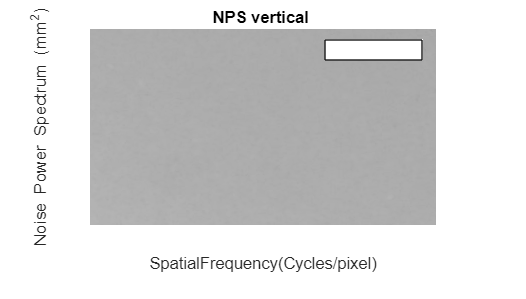

title('NPS vertical ')
ylabel('Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

% semilogy(l_NPSv,m_NPSvert)

%RADIAL NPS

%Before calculating the Radial NPS we first need to normalize the NPS to
%obtain the NNPS. To do so we divide
%the NPS results by the large area result or the air kerma squared.

aK =2.3 % Air Kerma in mGy

ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 95
      KeyType: char
    ValueType: any


aK = 2.3000

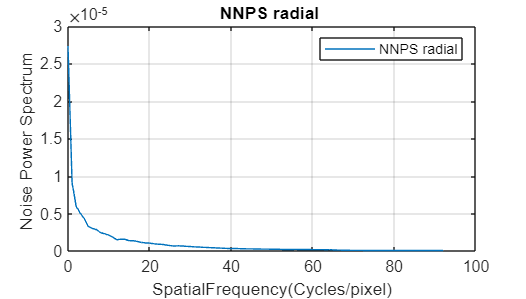


NNPS_calc = NPS./(aK).^2;

%For the radial NPS, we selecte the NPS values in radial frequency
%intervalls of [f,f+delta(f)], sum over all these values and divide by the
%number of values used, to obtain the average

% We start of by determining the length of the radial frequency intervall.
% We do this by determinig the maximum frequency in horizontal (u_max) and vertical direction (v_max). 
% If we add those  upp according to f= sqrt((u_max)^2 +(v_max)^2), we obtain the maximum radial frequency,
% which we can possibly select. Same is done for the minimum frequencies,
% so we can obtain the length of the radial frequency intervall.

v_max = length(l_NPSv);
u_max = length(l_NPSh);

u_0 = 1;
u_0 = 1;

%Determine maximum and minimum of radial frequency

f_max = sqrt((u_max.^2)+(v_max.^2));
f_0 = sqrt(2);

% A frequency step is bin = 0.01/pixelpitch; 
psize = 10/926;
bin = 0.01/psize;

f = f_0:f_max;
lf = length(f)-1; %Length of radial frequency intervall

% We determine the number of frequency steps by which we traverse the
% intervall.
% We take and substract the modulus to get a natural number of steps.

modbin = mod(lf,bin);
%Number of frequency steps ni
ni = ((lf-modbin)./bin);
%Define cell arrays to save the results
NPSf = cell(1, ni);
tNPSF = cell(1,ni); %To store the averaged results
%Initialize a cell array to store result for each of the ni frequency steps
for col = 1:ni
      NPSf{1,col} = 0;
end
%Next, we initialize an cell array, which stores every possible
%combination of frequency steps in horizontal direction. We can then go
%through all of these values and check, wether they fulfill our
%requirements. The requirement is that they have to be in a certain
%frequency intervall. All values with frequencies in these intervalls
%will then be averaged.
for u = 1:u_max;
   for v = 1:v_max;
       uv = sqrt((u.^2)+(v.^2));
       uvcell{u,v} =uv;
   end
end
%Now check intervals [f+(i-1)*deltaf;f+(i*deltaf)] for the NPS values and
%calculate their average.
for i = 1:ni
    %Running variable to note number of values in the interval

    l = 0;
    for u = 1:u_max-3
        for v = 1:v_max-3
            if uvcell{u,v} >= (1+(i-1)*bin) && uvcell{u,v} <= (1+(i)*bin) 
             l = l+1;   
             sumresult = sum(NNPS_calc(hzero+u,vzero+v));
             NPSf{1,i} = NPSf{1,i}+sumresult;

            end
        end
    end
    tNPSF{1,i} = (1./l)*NPSf{1,i};
end

% Finally, display the result
coll = 0:ni-1;
plot(coll, [tNPSF{1,coll+1}]);
legend('NPS radial')
title('NPS radial ')
ylabel('Noise Power Spectrum ')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

%Now display the other results to compare them. They 
% are displayed in their order.

m_NPSvert = m_NPSvert';

% Plot vertical and horizontal against one another
dose = 5.7; %in mikroGy
m_NNPShor = m_NPShor./(dose^2);
m_NNPSvert = m_NPSvert./(dose^2);

coll = 0:ni-1;
% plot(coll, [tNPSF{1,coll+1}]/(dose^2));
legend('NNPS radial')
title('NNPS radial ')
ylabel('Noise Power Spectrum ')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

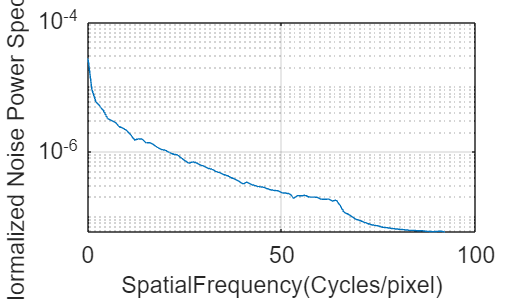


semilogy(coll, [tNPSF{1,coll+1}])
ylabel('Normalized Noise Power Spectrum ')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on
fontsize(14,'points')

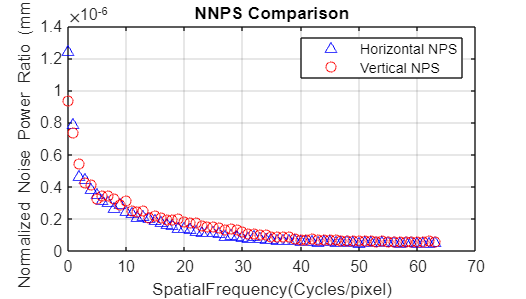

% axis([0 45 0 1]);

plot(l_NPSh,m_NNPShor,'b ^',l_NPSv,m_NNPSvert,'r o');
legend('Horizontal NPS', 'Vertical NPS')
title('NNPS Comparison')
ylabel('Normalized Noise Power Ratio (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)');
grid on

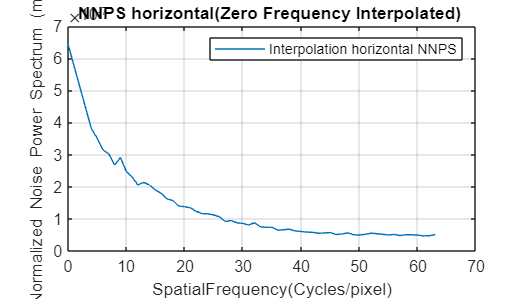


%%%%% Extrapolation for zero NNPS values
%Because the NPS values in the lower frequency often contain a substantial
%amount of noise, their caluculations can be assuemed to be incorrect. For
%correction, different interpolation techniques can be applied. Here we
%interpolate on the basis of the noise trend in the higher frequency
%regions.
M_NNPScor = m_NNPShor;
dfn = m_NNPShor(4)-m_NNPShor(5);
M_NNPScor(3) = m_NNPShor(4)+dfn;
M_NNPScor(2) = M_NNPScor(3)+dfn;
M_NNPScor(1) = M_NNPScor(2)+dfn;
plot(l_NPSh,M_NNPScor);

legend('Interpolation horizontal NNPS')
title('NNPS horizontal(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

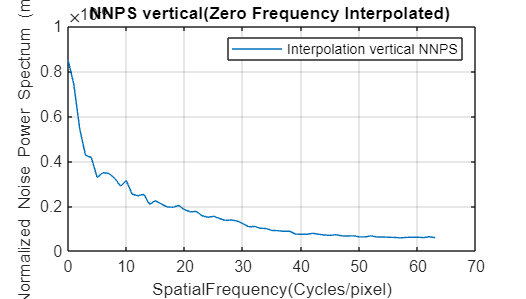


M_NNPScorv = m_NNPSvert;
dfnv = m_NNPSvert(2)-m_NNPSvert(3);
M_NNPScorv(1) = m_NNPShor(2)+dfn;
plot(l_NPSh,M_NNPScorv);
legend('Interpolation vertical NNPS')
title('NNPS vertical(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum (mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

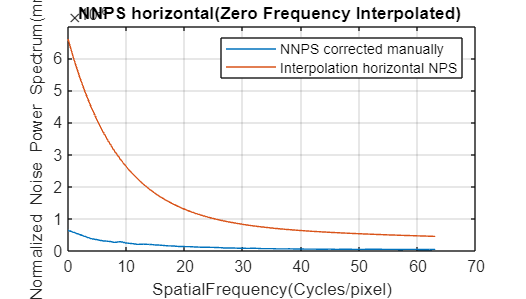



%%%% Interpolation with Curve fitter. The noise interpolations can also be
%%%% done employing the Curve fitter app.
x = l_NPSh;
a = 5.7114e-06;
b = -0.1140;
c =8.8428e-07;
d = -0.0107;
estra = a*exp(b*x)+c*exp(d*x);
 plot(l_NPSh,M_NNPScor,l_NPSh,estra);
legend('NNPS corrected manually','Interpolation horizontal NPS')
title('NNPS horizontal(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum(mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on


semilogy(l_NPSh,M_NNPScor);
legend('NNPS corrected manually','Interpolation horizontal NPS')

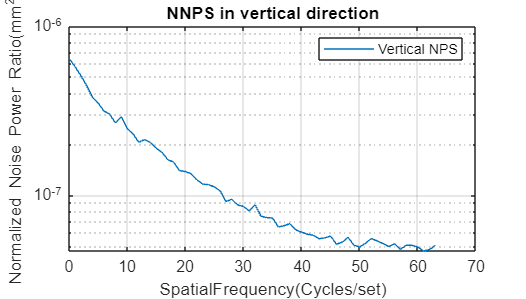

title('NNPS horizontal(Zero Frequency Interpolated) ')
ylabel('Normalized Noise Power Spectrum(mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on

%Plot the Vertical Direction indiviually
% plot(m_NNPSvert,'o','Color','r');
legend('Vertical NPS')
title('NNPS in vertical direcetion')
ylabel('NormalizedNoisePowerRatio(mm^2)')
xlabel('SpatialFrequency(Cycles/pixel)')
grid on


%CONVERSION TO CYCLES/SET
set = 1/(length(m_NNPSvert));

% plot(l_NPSv*set,m_NNPSvert,'o','Color','r');
legend('Vertical NPS')
title('NNPS in vertical direction')
ylabel('Normalized Noise Power Ratio(mm^2)')
xlabel('SpatialFrequency(Cycles/set)')
grid on

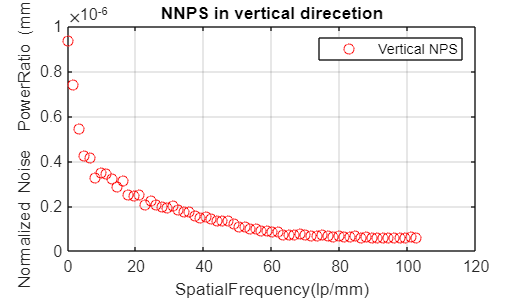


%%% LINEPAIR PER MM

pp = ;                        %pixelpitch in mm
set = set*(1/pp);

plot(l_NPSv*set,m_NNPSvert,'o','Color','r');
legend('Vertical NPS')
title('NNPS in vertical direcetion')
ylabel('Normalized Noise  PowerRatio (mm^2)')
xlabel('SpatialFrequency(lp/mm)')
grid on

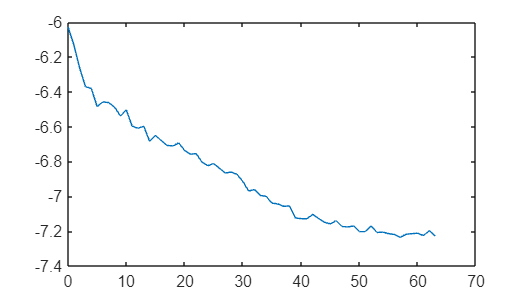


%%%DETECTIVE QUANTUM EFFICIENCY

%For the DQE, divide MTF^2 by Normalized Noise Power Spectrum (NNPS)
% times the average X-ray input fluency per image aquisition. 

% dose= 4.*10.^-3; %Just so, that it is predefined

o = 0:(region_size/2)-1;
q = ;

% Plor the vertical NPS again
m_NNPSvert = m_NNPSvert(1:(region_size/2));
% m_NPSvert = m_NPSvert:/max(m_NPSvert);
plot(o,log10(m_NNPSvert))

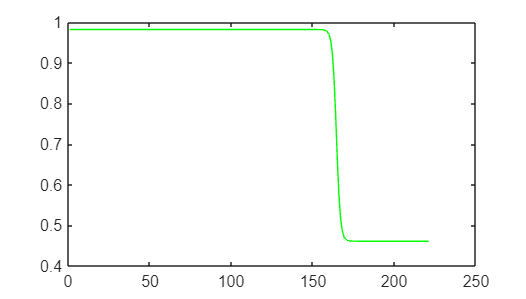

fo = 0:length(hl_gffitMTF)-1;
lps = 1/length(fo);
lps = lps*(1/psize);


%Calulate and plot the NNPS

%Plot the previously fitted Fermi-Dirac function. 

lmf = 1:221;
fdfit2 = @(b)b(1)./(exp((l_selESf-b(2))./b(3))+1)+b(4);
b = fdfit_para;
plot(lmf,fdfit2(b),'-g');

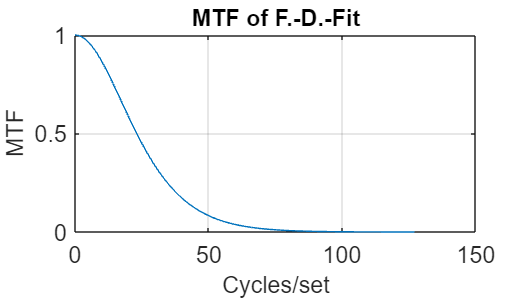


%LSF of FD fit

Lsftest = abs(diff(fdfit2(b)));
selLSF= abs(diff(selESF)); 

%MTF of FD fit

Ltest = length(Lsftest);         %Now the fitted Fermi-Dirac-LSF data
ntest = 2^nextpow2(Ltest);

fdfitman_MTF =abs(fft(Lsftest,ntest));         %FT of the LSF
fdfitman_MTF = fdfitman_MTF/max(fdfitman_MTF);    %Norm
hhl_fdfitmanMTF = fdfitman_MTF(1:length(fdfitman_MTF)/2);  %Again only interested in the real results 
hh = 0: length(hhl_fdfitmanMTF)-1;


plot(hh,hhl_fdfitmanMTF);
title('MTF of F.-D.-Fit')
xlabel('Cycles/set')
ylabel('MTF')
grid on
fontsize(14,"points")

% axis([0 350 -20 250])

set = 1/(length(hhl_fdfitmanMTF));
pp = (9.6.*(10.^-3)) %pixelpitch in mm

pp = 0.0096

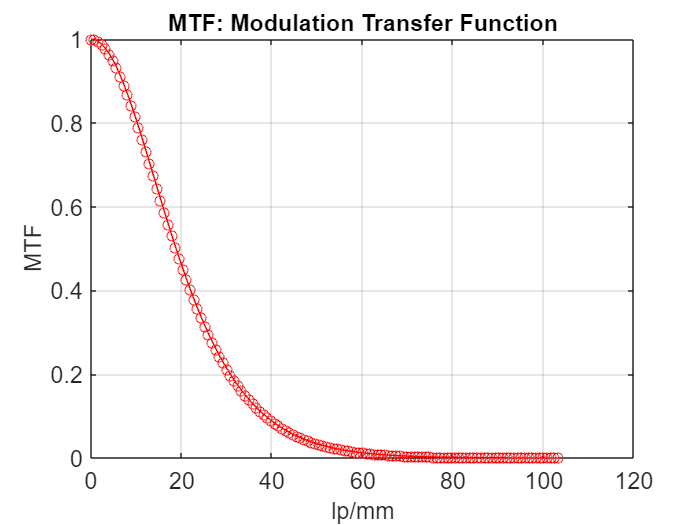

set = set*(1/pp);

figure;
plot(hh*set,hhl_fdfitmanMTF,'-o r');
title('MTF: Modulation Transfer Function')
ylabel('MTF')
xlabel('lp/mm')
grid on
fontsize(14,"points")

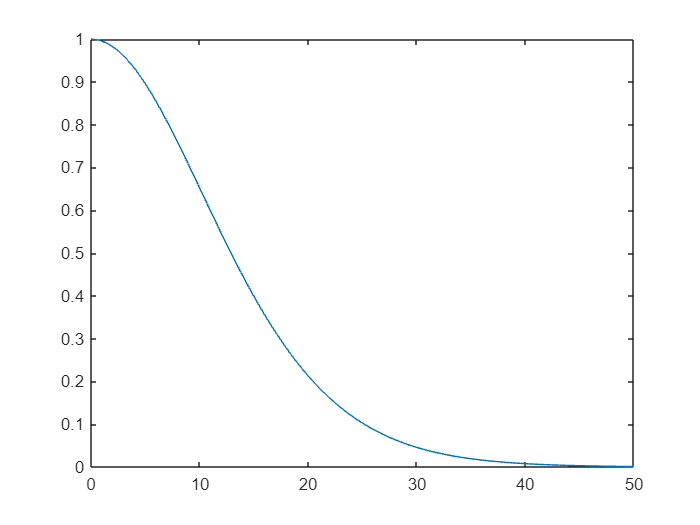


% m_NNPSvert = m_NPSvert*(1/(dose^2));
% plot(o,log10(m_NPSvert));

%Calculate and plot MTF^2

% hldqe_gffitMTF= hl_gffitMTF(1:(region_size/2));
hldqe_gffitMTF= hhl_fdfitmanMTF;
hldqe_gffitMTF = (hldqe_gffitMTF).*(hldqe_gffitMTF);

plot(hh*set,hldqe_gffitMTF)
axis([0 50 0 1]);

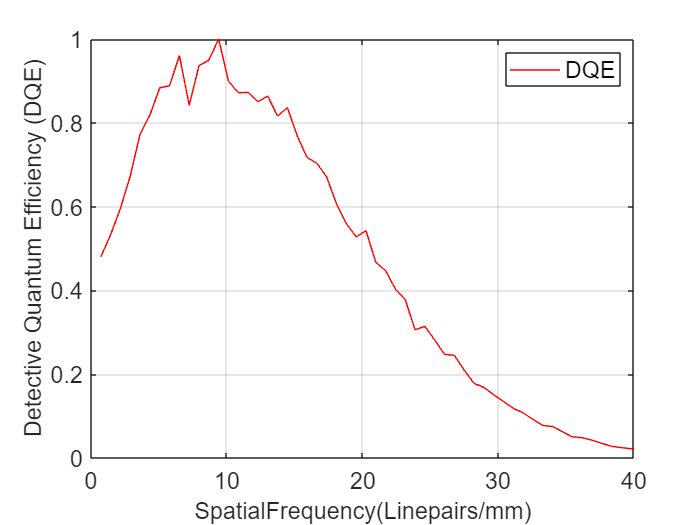


%Now combine  in order to obtain the DQE. Usually, NNPS and MTF arrays are
%of different sizes, so this has to be considered.

% M_NNPScor = M_NNPScor(1:(region_size/2));
dq = hldqe_gffitMTF(1:length(M_NNPScor));
% M_NNPScor = M_NNPScor(1:63);
beef = dq./M_NNPScor;
% beef = beef.*(1./(q*dose));
beef = beef./max(beef);


fl = 1:length(M_NNPScor);
plot(fl*lps,beef,'r');
legend('DQE')
% title('DQE ')
ylabel('Detective Quantum Efficiency (DQE)')
xlabel('SpatialFrequency(Linepairs/mm)')
axis([0 40 0 1]);
grid on
fontsize(14,'points')

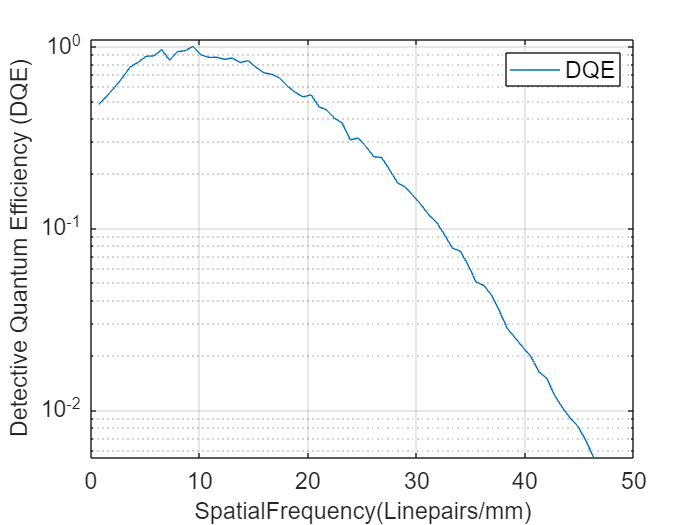


% Logarithmic Plot

semilogy(fl*lps,beef);
legend('DQE')
% title('DQE ')
ylabel('Detective Quantum Efficiency (DQE)')
xlabel('SpatialFrequency(Linepairs/mm)')
axis([0 50 0 1.1]);
grid on
fontsize(14,'points')


% Give Function Values as csv file. Again, if data shall be plotted
% outside of MATLAB.

lpmm =  fl*lps; % Safe MTF and lp/mm in one column
lpmm = lpmm';
dqevalues = beef';
result2=[lpmm dqevalues];
writematrix(result2,'DQE.txt','Delimiter',';') % Write a csv file DQE.csv with the wanted data
  
% estra = estra(1:length(hldqe_gffitMTF));
hldqe_gffitMTF = hldqe_gffitMTF(1:93);
beefest = q*hldqe_gffitMTF./[tNPSF{1,fl+1}];

Arrays have incompatible sizes for this operation.

Related documentation

% beef = beef.*(1./(q*dose));
beefest = beefest./max(beefest);

plot(fl*lps,log10(beefest),'r');
legend('Detective Quantum Efficiency for horizontal NPS')
title('DQE ')
ylabel('Detective Quantum Efficiency')
xlabel('SpatialFrequency(Linepairs/mm)')
grid on
semilogy(fl*lps,beefest);
